# How photons become electrons and preserve the Poisson distribution

The distribution of photons arriving at the sensor (irradiance) is Poisson.  Why is the Poisson distribution preserved as we transform light to electrons?

## The Poisson distribution

The Poisson distribution describes the statistics of a series of 'events'.  The key property of a Poisson distribution is that the likelihood of an event is the same over each small interval of time.  For light an event is the arrival of a photon. Incident light at a location follows the Poisson distribution because in each small interval of time, $\delta T$ the probability that a photon will arrive is constant, $\rho$. 

We simulate the set of photon arrivals this way, using the binomial distribution for each moment in time.

deltaT    = 1e-6;     % A microsecond
rho       = 1e-4;     % Chance of a photon in deltaT
T = deltaT:deltaT:1;  % Time samples
photons = binornd(1,rho,length(T),1);  % The binomial random distribution

At each moment in time an event happens, or not, with probability $\rho$. Here is a plot with a line at each moments when there is (1) or is not (0) a photon.

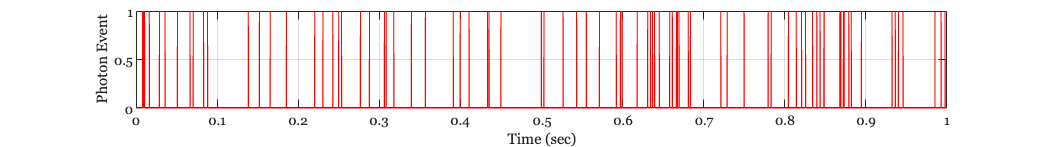

f = ieNewGraphWin; 
plot(T,photons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Photon Event'); grid on

fprintf('In a second, there were %d photons\n',sum(photons));

In a second, there were 86 photons


## Photon to electron conversion

At the sensor, an event is the creation of an electron. For a CMOS or CCD image sensor, each photon turns into one electron or no electrons.   Suppose the probability of a photon generating an electron is $\epsilon$.  Let's set epsilon to one half, as an example.

epsilon = 0.5;

The probability of conversion is the same in each interval.  Here is the probability of the conversion is also a Poisson distribution.

eConversion = binornd(1,epsilon,length(T),1);

This is not worth plotting because with $\epsilon$ so large.  The graph of eConversion will just look like a solid red square.

## The distribution of electrons

We will have an electron in the interval $\delta T$ if 

- There is a photon in that interval, and 

- The electron conversion value is 1.

The probability is the same in each little time interval, and thus the whole calculation is Poisson.

electrons = photons .* eConversion;

Here is a plot of the electrons, which is a subset of the times when there is a photon

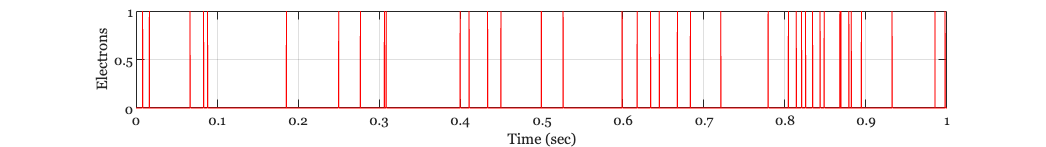

f = ieNewGraphWin; plot(T,electrons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Electrons'); grid on

fprintf('Combining photons with conversion likelihood, there were %d electrons\n',sum(electrons));

Combining photons with conversion likelihood, there were 40 electrons


## Equivalent calculation

We do not have to do the calculation in two steps.  The calculation would be the same distribution if we combine the two probabilities up front. 

electrons2 = binornd(1,rho*epsilon,length(T),1);

This produces the same results as doing the calculation in two steps.

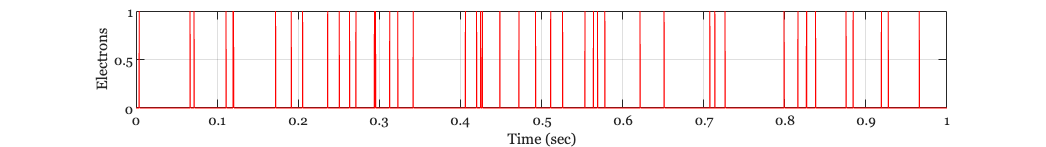

f = ieNewGraphWin; plot(T,electrons2);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)');
ylabel('Electrons'); grid on

fprintf('The alternative calculation - use the binomial with the combined probabilities.\nThere were %d electrons\n',sum(electrons));

The alternative calculation - use the binomial with the combined probabilities.
There were 40 electrons


## Additional questions:  What about photon multipliers and SPADs?

This logic does not apply if each photon can become multiple electrons.  This is what we might observe for photomultipliers (vacuum tube technology) or avalanche photodiodes, the semiconductor based equivalent. Even so, in these applications some people use the Poisson as an approximation. 

How about doing that calculation to see how well it works?

Note that the key property of the Poisson distribution (an equal chance of an event in every small interval of time) does not hold.  The generation of the electrons will be clustered around the times when a photon arrives.  But how well can we approximate the total number of electrons in a longer interval?  Will that be Poisson, or not?

An avalanche photodiode with very high gain is called a "single photon avalanche detector" (SPAD).  In that case, the Poisson distribution arises from the physics associated with the conversion of a single photon.